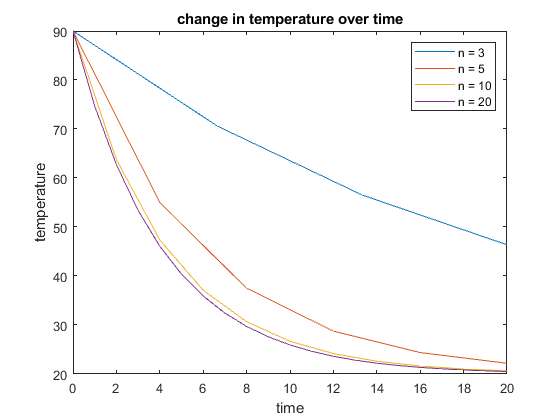

N = [3 5 10 20];

dt1 = 20/N(1);
dt2 = 20/N(2);
dt3 = 20/N(3);
dt4 = 20/N(4);

t1 = 0:dt1:20;
t2 = 0:dt2:20;
t3 = 0:dt3:20;
t4 = 0:dt4:20;

[T1] = IVPsolver(N(1));
[T2] = IVPsolver(N(2));
[T3] = IVPsolver(N(3));
[T4] = IVPsolver(N(4));

plot(t1,T1)
hold on
plot(t2,T2)
hold on
plot(t3,T3)
hold on
plot(t4,T4)
xlabel('time')
ylabel('temperature')
title('change in temperature over time')
legend('n = 3','n = 5', 'n = 10', 'n = 20')

function [T] = IVPsolver(N)
    dt = 20/N;
    t = 0:dt:20;
    
    SOL = NaN(1,length(t));
    SOL(1,1) = 90;
    
    for i = 2:length(t)
        SOL(1,i) = SOL(1,i-1) + dt*(-0.25*SOL(1,i-1) + 0.25*20);
        SOL(1,i) = SOL(1,i-1) + dt/2*(-0.25*SOL(1,i-1) + 0.25*20 - 0.25*SOL(1,i) + 0.25*20);
    end
    
    T = SOL(1:length(t));
end